%opt.max_rate = 0.25/10;
opt.track_len = 120; %cm
%opt.field_std = 3; %cm
opt.out_noise = 120; %cm
opt.max_v = 30; %cm/s
opt.noise_sigma = 10; %cm
opt.session_time = hours(0.5); %duration
opt.dt = seconds(1/20); %duration

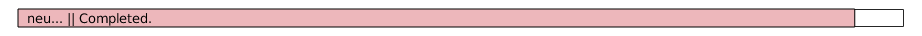

t_ = tic;

total_n_cells = 500;
d_neu = 30;
ns = unique([1, d_neu:d_neu:total_n_cells, total_n_cells]);

%progressbar('reps...', 'neu...');
progressbar('neu...');
n_reps = 20;

[mse_short, mse_sh_short] = deal(zeros(n_reps, numel(ns)));

for n_ix = numel(ns):-1:1
parfor r_ix = 1:n_reps
    
        [mse_short(r_ix, n_ix), mse_sh_short(r_ix, n_ix)] = decoding_simulator(ns(n_ix), opt);
        %progressbar([], n_ix / numel(ns));
    
    %progressbar(r_ix/n_reps);
    %fprintf('Done rep %d\n', r_ix);
end
progressbar((numel(ns) - n_ix + 1)/numel(ns));
end

toc(t_);

Elapsed time is 93.084188 seconds.


[fr_real_short, gof_real_short] = createFit_infoSaturation(ns, mean(1./mse_short))

fr_real_short =      General model:
     fr_real_short(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =   0.0002666  (0.0002472, 0.0002859)
       N =       131.5  (117.8, 145.2)

gof_real_short = struct with fields:
           sse: 3.9210e-06
       rsquare: 0.9961
           dfe: 16
    adjrsquare: 0.9958
          rmse: 4.9504e-04


[fr_shuf_short, gof_shuf_short] = createFit_infoSaturation(ns, mean(1./mse_sh_short))

fr_shuf_short =      General model:
     fr_shuf_short(x) = I_0*x/(1+x/N)
     Coefficients (with 95% confidence bounds):
       I_0 =    0.000234  (0.0002175, 0.0002505)
       N =       572.8  (469.2, 676.4)

gof_shuf_short = struct with fields:
           sse: 2.4703e-05
       rsquare: 0.9960
           dfe: 16
    adjrsquare: 0.9957
          rmse: 0.0012


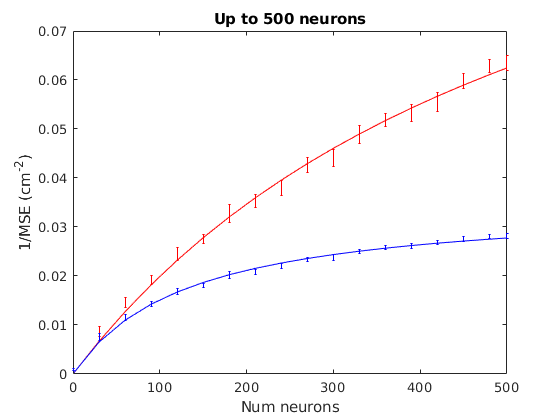


figure;
ep(ns, 1./mse_sh_short, 'r.'); hold on;
plot(ns, fr_shuf_short(ns), 'r');

ep(ns, 1./mse_short, 'b.');
plot(ns, fr_real_short(ns), 'b');
xlabel 'Num neurons'
ylabel '1/MSE (cm^{-2})'
title 'Up to 500 neurons'

[mse, mse_sh, X_noise, tr_bins] = decoding_simulator(2, opt);
sqrt(mse)

ans = 5.7962

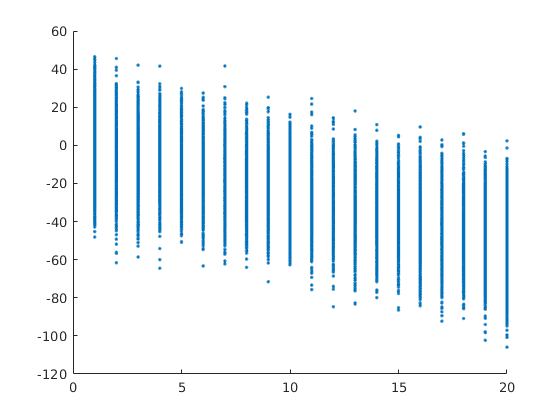

figure;
scatter(tr_bins, mean(X_noise,1), '.');

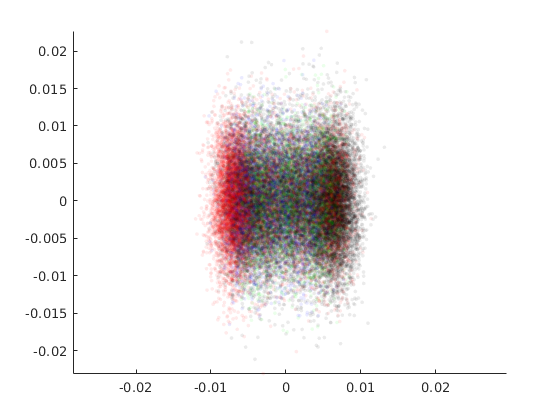


alpha = 0.08;
XS = Utils.pls_short(X_noise.', tr_bins);

figure;
scatter(XS(:,1), XS(:,2), 8, Utils.colorcode(tr_bins),...
    'filled', 'MarkerFaceAlpha', alpha);
axis equal;

function [mse, mse_sh, X_noise, tr_bins] = decoding_simulator(num_neurons, opt)
sig_dir = randn(num_neurons, 1);

mean_resp = @(x) x .* sig_dir;
samp_resp = @(x) mean_resp(x) + opt.out_noise.*randn(num_neurons, numel(x));

t = seconds(seconds(0):opt.dt:opt.session_time);
x_traj = opt.track_len .* sin(opt.max_v./opt.track_len .* t).^2;
input_noise = opt.noise_sigma*randn(size(x_traj));

%X_no_noise = samp_resp(x_traj);
X_noise = samp_resp(x_traj + input_noise);

dt_opts = DecodeTensor.default_opt;
[~,~,tr_s,tr_e,tr_dir,tr_bins,~] = DecodeTensor.new_sel([x_traj(:), 0*x_traj(:)], dt_opts);
data_tensor = DecodeTensor.construct_tensor(X_noise.', tr_bins, dt_opts.n_bins, tr_s, tr_e);

alg = fastdlda;
err_res = DecodeTensor.decode_all(data_tensor, tr_dir, opt.track_len/dt_opts.n_bins, alg, [], []);

mse = err_res.MSE.unshuffled;
mse_sh = err_res.MSE.shuffled;
end

function ep(n, m, varargin)
m_mean = mean(m, 1);
samples = size(m, 1);
m_std = std(m, [], 1);
m_sem = m_std ./ sqrt(samples);
errorbar(n, m_mean, m_sem.*1.96, varargin{:},...
    "CapSize", 1, "Marker", "none", 'LineStyle', "none");
end